# Asesoria

### Metodos Numericos

#### 2022-2S : 15/11/2022

#### ***Neural Network Calculations***

*Variation of parameters and values expected for the Neural Network*

% Design parameters expected
tau = 1 * 1e-6; n = 3; omega = 10 * 1e3;
Rt = 1e3; Cc = 1e-6; Cd = 1e-6; E = 2;
Rf = 1 *1e3; Rc = 1e2;

% Design parameters obtained
alpha = 1 / (tau * n * omega)
ResistanceRatio = E / (Rt * 2 * omega * Cc)
Rl = Rf / (omega * Rc * Cc), Rs = Rf / (2 * omega * Rc * Cc)
VoltageGain = Rf / (Rl * Rt * Cc)

#### ***Neural Network Calculations***

*Numerical convergence of the values.*

clear

alpha = 33.3333

ResistanceRatio = 0.1000

Va = [-1.3 1.7 .5 2.2 -2.6 1.5 -.6 .9 -1.2 1.1];

Rl = 1000

Rs = 500

omega = 10 *1e3; beta = 10 * 1e3; tau = 1 * 1e-6; alpha = 1;

VoltageGain = 1000

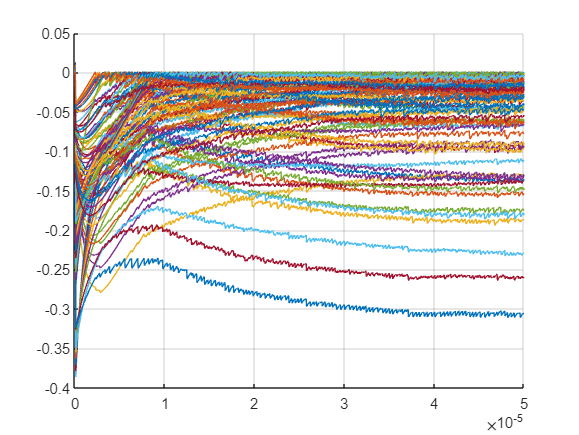


C = [-13 -11.7 -10.4 -9.1  -7.8  -6.5 -5.2  -3.9 -2.6 -1.3;
      17  15.3  13.6  11.9  10.2  8.5 6.8   5.1  3.4  1.7 ;
      5   4.5   4     3.5   3     2.5 2     1.5  1    .5  ;
      22  19.8  17.6  15.4  13.2  11  8.8   6.6  4.4  2.2 ;
     -26 -23.4 -20.8 -18.2 -15.6 -13 -10.4 -7.8 -5.2 -2.6 ;
      15 13.5  12    10.5   9    7.5  6     4.5  3    1.5 ;
     -6  -5.4 -4.8   -4.2  -3.6  -3  -2.4  -11.8 -1.2 -.6 ;
      9   8.1  7.2    6.3   5.4   4.5 3.6   2.7   1.8  .9 ;
     -12 -10.8 -9.6  -8.4  -7.2  -6   -4.8 -3.6  -2.4 -1.2;
      11  9.9  8.8   7.7   6.6   5.5  4.4   3.3  2.2  1.1];

Za = [C(1, :) C(2, :) C(3, :) C(4, :) C(5, :) C(6, :) ...
                        C(7, :) C(8, :) C(9, :) C(10, :)];
Za =  alpha * (sum(Va) + Za);
Za(Za > 0) = Za(Za > 0) *alpha; Za(Za < 0) = 0;

k = 1; t = 50 * tau;
a = 0; b = t; M = 1e3;

Za = zeros(1, 100);

[t, U] = heuns("F", a, b, Za, M);

% Grafications of data

clf('reset')
hold on

for k = 1:100
    plot(t, U(:, k), 'DisplayName', 'Neuron' + string(k))
end

grid on
hold off
tolerance = - 5e-2;

clf('reset')
hold on

for k = 1:100
    if U(end, k) < tolerance

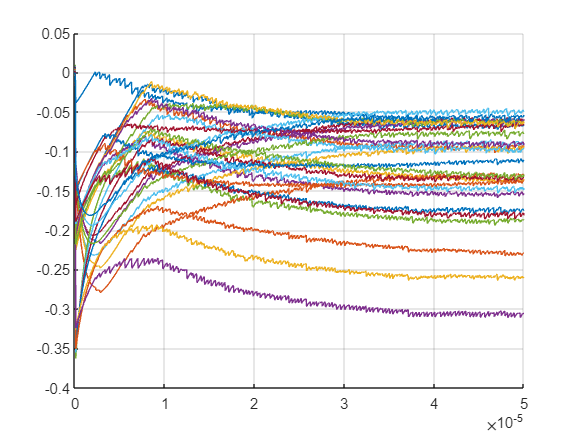

        plot(t, U(:, k), 'DisplayName', 'Neuron' + string(k))
    end
end

grid on
hold off
clf('reset')
hold on
plot(t, U(:, 5), '-',  'DisplayName', 'Neuron 51')
plot(t, U(:, 1 + 10), '-',  'DisplayName', 'Neuron 12')
plot(t, U(:, 3 + 80), '-',  'DisplayName', 'Neuron 93')
plot(t, U(:, 4 + 60), '-',  'DisplayName', 'Neuron 74')
plot(t, U(:, 5 + 20), '-',  'DisplayName', 'Neuron 35')

plot(t, U(:, 6 + 70), '-',  'DisplayName', 'Neuron 86')
plot(t, U(:, 10 + 6), '-',  'DisplayName', 'Neuron 107')
plot(t, U(:, 8 + 5), '-',  'DisplayName', 'Neuron 68')
plot(t, U(:, 9 + 10), '-',  'DisplayName', 'Neuron 29')
plot(t, U(:, 4 + 90), '-',  'DisplayName', 'Neuron 410')
legend('Location', 'best')
grid on
hold off

### Revisemos los preparatorios compartidos

*Detalladamente veamos que:*

`Punto 1. Verifiquemos la cuadratura`

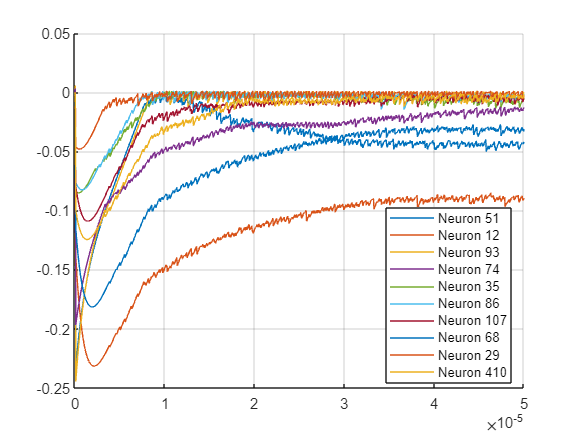

clear
syms f(x)
syms A B C x real

% Grado 0
f(x) = 1;
Eq0 = int(x*f(x), 0, 2) == A * f(0) + B * f(1) + C * f(2)

% Grado 1
f(x) = x;
Eq1 = int(x*f(x), 0, 2) == A * f(0) + B * f(1) + C * f(2)
% Grado 2
f(x) = x^2;
Eq2 = int(x*f(x), 0, 2) == A * f(0) + B * f(1) + C * f(2)
% Verifiquemos por el momento la convergencia de la regla
S = solve(Eq0, Eq1, Eq2)
% Grado 3
f(x) = x^3;
Eq3 = int(x*f(x), 0, 2) == A * f(0) + B * f(1) + C * f(2)

$$Eq0 = 2=A+B+C$$

% Verifiquemos por el momento la convergencia de la regla
S = solve(Eq0, Eq1, Eq2, Eq3)

Veamos que la máxima convergencia se da para $n=2$, por lo que el grado de precisión de la regla es **2**

`Punto 2. Resolución de un PVI`

clear

$$Eq1 = \frac{8}{3}=B+2\,C$$

syms f(t, y)

f(t, y) = exp(2*t) * atan(y);

$$Eq2 = 4=B+4\,C$$

df(t, y) = diff(f, t) + diff(f, y) * f(t, y);


S = struct with fields:
    A: 0
    B: 4/3
    C: 2/3


df(t, y) = [f, df, 0, 0];
df = matlabFunction(df);


$$Eq3 = \frac{32}{5}=B+8\,C$$

T2 = taylor(df, -2, 1, 1, 4);
T = T2(:, 1); Y = T2(:, 2);

S = struct with fields:
    A: [0×1 sym]
    B: [0×1 sym]
    C: [0×1 sym]



Y(T == .25)

`Punto 4. Integración númerica Simpson & Trapecio.`

clear
syms f(x)
syms n x real

f(x) = x * log(x);
a = 1; b = 5; h = (b - a) / n;

% Para la regla de Simpson necesitamos f^(iv)
d4f(x) = diff(f, x, 4);
tolerance = 1e-9; Error = -h^4 / 180 * (b - a);

X = linspace(1, 5, 1e4); maxd4f = max(d4f(X));


ans = 1.5229

n = solve(tolerance > abs(Error * maxd4f), n > 0);
n = ceil(n)
% Para la regla de Trapecio necesitamos f^(ii)
clear n
syms n real

d2f(x) = diff(f, x, 2);
tolerance = 1e-4; Error = -h^2 / 12 * (b - a);

X = linspace(1, 5, 1e4); maxd2f = max(d2f(X));

n = solve(tolerance > abs(Error * maxd2f), n > 0);
n = floor(n)
% Aplicamos los métodos a la función
f = matlabFunction(f);

I = simprl(f, a, b, 30)

$$n = 328$$

I = traprl(f, a, b, 100)

`Punto 5. Integración númerica Creación de cuadraturas`

clear

f = @(x) 4 * sin(x.^2) .* cos(x / 9);

Isimple = reglaSimple(f, -2, 4)
Icomp = reglaCompuesta(f, -2, 4, 33)

`Punto 7. Formula de cuadratura empleada para aproximar la integral.`

clear
syms f(t, x)

f(t) = 1 / t;

$$n = 231$$

f(x) = f(x/2 + 2.5) /2;

cuad = vpa(3/2 * f(-1/3) + 1/2 * f(1), 5)

### Duda Mateo

`Constante de L que acota la función`

clear

I = 14.1180

format long

I = 14.1182


Y = linspace(-1, 1, 1e6)
f = @(y) y .* exp(-3*y.^2);

clf('reset')
fplot(f)
grid on

Isimple = 10.3156

max(f(Y)), f(sqrt(1/6))

Icomp = 6.1483

max(f(Y)) * 6 *exp(-1) + 4

clear

A = [4/9 25/9 4; 8/27 125/27 12; 16/81 625/81 32];
b = [8/3 4 32/5]';
A\b

rref([A, b])

$$cuad = 0.40476$$

`Punto 5. Cuadraturas empleadas`

function I = reglaSimple(f, a, b)
% Entrada  - f funcion integrando creada con @
%          - a y b son los limites superior e inferior de integracion
% Salida   - I es el valor de la integral númerica

Y =   -1.000000000000000  -0.999997999998000  -0.999995999996000  -0.999993999994000  -0.999991999992000  -0.999989999990000  -0.999987999988000  -0.999985999986000  -0.999983999984000  -0.999981999982000  -0.999979999980000  -0.999977999978000  -0.999975999976000  -0.999973999974000  -0.999971999972000  -0.999969999970000  -0.999967999968000  -0.999965999966000  -0.999963999964000  -0.999961999962000  -0.999959999960000  -0.999957999958000  -0.999955999956000  -0.999953999954000  -0.999951999952000  -0.999949999950000  -0.999947999948000  -0.999945999946000  -0.999943999944000  -0.999941999942000  -0.999939999940000  -0.999937999938000  -0.999935999936000  -0.999933999934000  -0.999931999932000  -0.999929999930000  -0.999927999928000  -0.999925999926000  -0.999923999924000  -0.999921999922000  -0.999919999920000  -0.999917999918000  -0.999915999916000  -0.999913999914000  -0.999911999912000  -0.999909999910000  -0.999907999908000  -0.999905999906000  -0.999903999904000  -0.99990199990

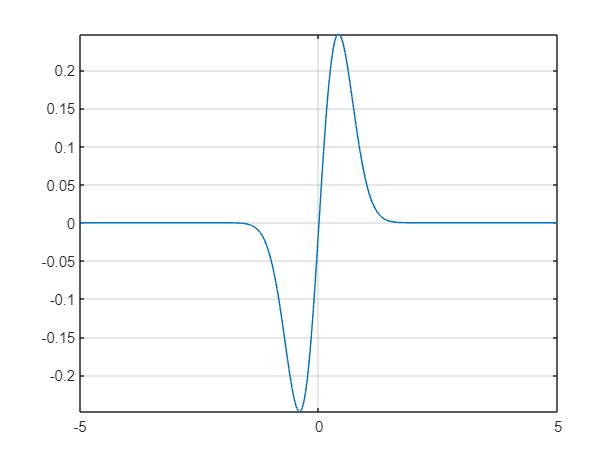


h = (b - a) / 3;

x1 = a + 3/5*h;
x2 = a + 9/5*h;

x3 = a + 3*h;

ans =    0.247615104940445


ans =    0.247615104941602


ans =    4.546555038586594


I = h/4 * (5*feval(f, x1) + 5*feval(f, x2) + 2 * feval(f, x3));
end

function I = reglaCompuesta(f, a, b, M)
% Entrada  - f funcion integrando creada con @
%          - a y b son los limites superior e inferior de integracion

ans =    1.042105263157896
   0.788210526315789
   0.003508771929825


%          - M es el número de sub-intervalos de la regla
% Salida   - I es el valor de la integral númerica

ans =    1.000000000000000                   0                   0   1.042105263157895
                   0   1.000000000000000                   0   0.788209606986900
                   0                   0   1.000000000000000   0.003508771929825



if not(rem(M, 3) == 0)
    error('M debe ser múltiplo de 3')
end

h = (b - a) / M;
I = 0;

for k = 1:M/3
    Init = a + 3*(k - 1)*h;
    End =a + 3*k*h;

    I = I + reglaSimple(f, Init, End);
end

end